## Q1

Let's use the 4 cornors of each books as the desired points

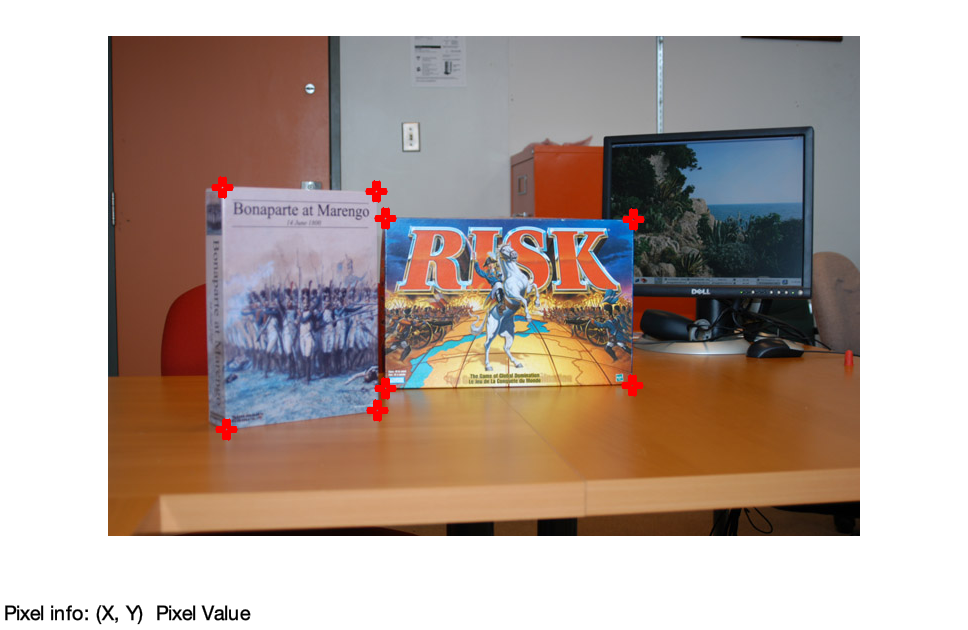

I1 = imread('p11.jpg');
imshow(I1);
impixelinfo;
hold on;
plot(115,152, 'ro', 'LineWidth', 5);
plot(269,156, 'ro', 'LineWidth', 5);
plot(119,394, 'ro', 'LineWidth', 5);
plot(270,375, 'ro', 'LineWidth', 5);
plot(278,183, 'ro', 'LineWidth', 5);
plot(526,184, 'ro', 'LineWidth', 5);
plot(278,353, 'ro', 'LineWidth', 5);
plot(525,350, 'ro', 'LineWidth', 5);
hold off;

*Bonaparte at Marengo*

Left top: (115,152)

Right top: (269,156)

Left Bottom: (119,394)

Right Bottom: (270,375)

*Risk*

Left top: (278,183)

Right top: (526,184)

Left Bottom: (278,353)

Right Bottom: (525,350)

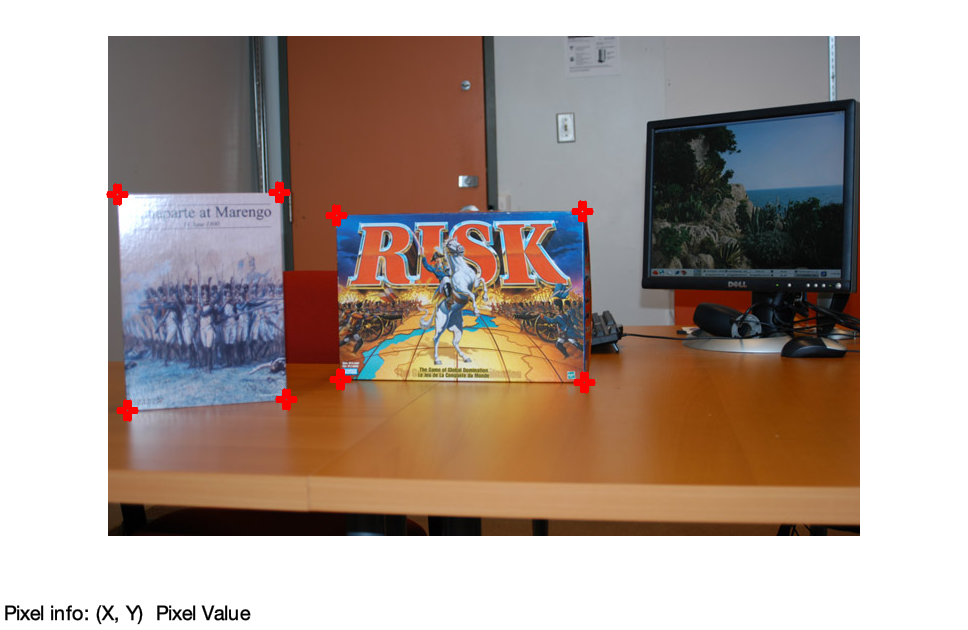

I2 = imread('p12.jpg');
imshow(I2);
impixelinfo;
hold on;
plot(10,159, 'ro', 'LineWidth', 5);
plot(172,157, 'ro', 'LineWidth', 5);
plot(20,375, 'ro', 'LineWidth', 5);
plot(179,364, 'ro', 'LineWidth', 5);
plot(229,180, 'ro', 'LineWidth', 5);
plot(475,176, 'ro', 'LineWidth', 5);
plot(233,344, 'ro', 'LineWidth', 5);
plot(477,347, 'ro', 'LineWidth', 5);
hold off;

*Bonaparte at Marengo*

Left top: (10,159)

Right top: (172,157)

Left Bottom: (20,375)

Right Bottom: (179,364)

*Risk*

Left top: (229,180)

Right top: (475,176)

Left Bottom: (233,344)

Right Bottom: (477,347)

Now load 8 points and compute F

L=[115 152;269 156;119 394;270 375;278 183;526 184;278 353;525 350];

R=[10 159;172 157;20 375;179 364;229 180;475 176;233 344;477 347];

F=Find_F(L,R,true);
disp('The Fundmental matrix F is');

The Fundmental matrix F is


disp(F);

   -0.0000    0.0000   -0.0005
   -0.0000    0.0000   -0.0050
    0.0009    0.0050   -0.2934



disp('The rank of F is');

The rank of F is


disp(rank(F));

     2



## Q2

Use RANSAC function

I1 = imread('p11.jpg');
I2 = imread('p12.jpg');
[wide,long,chan]=size(I1);
figure; ax = axes;
[F,pair]=RANSAC_F(I1,I2,0.01,30,5000,8);
%F=SurfFeaturepoints2("p11.jpg","p12.jpg")
disp(pair);

   207   294     1   107   287     1
   158   297     1    57   289     1
   677   181     1   717   166     1
   547   125     1   588   109     1
   358   230     1   306   225     1
   368   332     1   317   325     1
   547   125     1   588   109     1
   406   231     1   353   226     1
   199   309     1   100   301     1
   409   269     1   357   264     1
   490   266     1   439   261     1
   199   315     1   100   306     1
   501   273     1   451   267     1
   439   267     1   386   262     1
   224   304     1   126   296     1
   220   313     1   122   304     1
   482   266     1   430   260     1
   356   277     1   304   271     1
   465   261     1   414   256     1
   320   275     1   271   269     1
   268   295     1   174   289     1
   248   300     1   152   293     1
   645   246     1   683   238     1
   632   246     1   670   237     1
   440   279     1   388   273     1
   393   275     1   341   269     1
   673   245     1   711   237     1
 

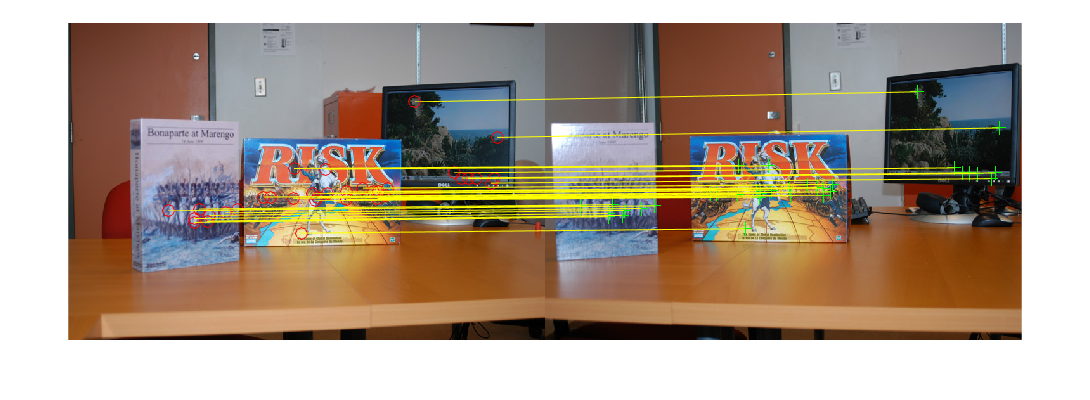

showMatchedFeatures(I1,I2,pair(:,1:2),pair(:,4:5),'montage','Parent',ax);

## Q3

Find epipoles e1 and e2

e1=null(F');
e2=null(F);

let e1,e2 = (eu,ev,1) 

e1=e1./e1(3);
e2=e2./e2(3);

Calculate H1

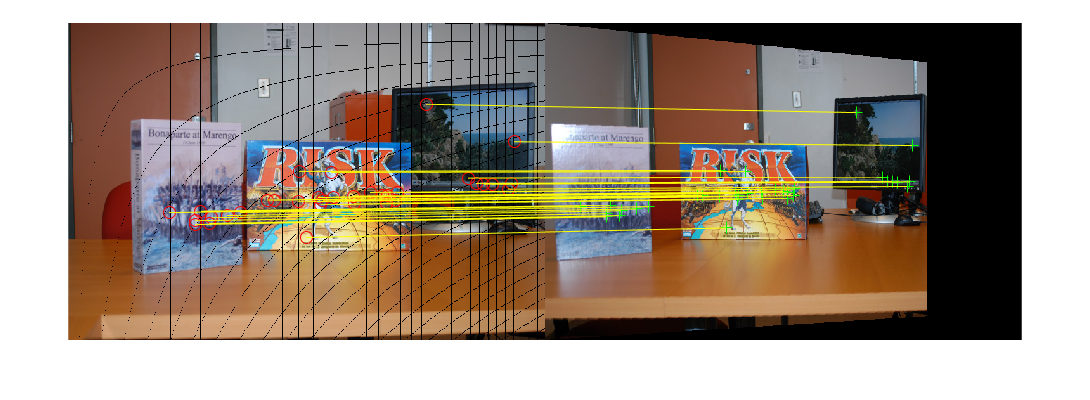

h1=find_h(e1);
h2=find_h(e2);
new_img=apply_homo(I1,h1);
points1=transfer_points(pair(:,1:3),h1);
new_img2=apply_homo(I2,h2);
points2=transfer_points(pair(:,4:6),h2);

showMatchedFeatures(new_img,new_img2,points1(:,1:2),points2(:,1:2),'montage','Parent',ax);